# Lab 5 - Compensator Design & Implementation

Name: Sam Kramer

Define the sampling parameters

clc; close all; format compact

fs = 1000;      % sample rate (Hz)
ts = 1/fs;      % sample period (sec)

Only change the font size here if the plot font is too big or too small

set(0,'defaultaxesfontsize',10);

## Load the Motor Model from Lab 4  [2 pts total]

**[2 pts]**  Load and display the continuous-time motor model.

NOTE:  If your motor model from Lab 4 is not correct or is not accurate enough, you will have a lot of difficulty with Lab 5.  It is important to fix any errors you may have from the Lab 4 motor model before starting this lab.

% -- Define system parameters
j = 2.5*10^-5;      % Total rotational inertia 
b = 1*10^-6;        % Tota rotational damping
Kt = 0.042;         % Torque constant
Ke = 0.042;         % Velocity constant
L = 1.16*10^-3;     % Motor inductance
R = 8.4;            % Motor resistance

% -- LTI transfer function of motor
num = [0 0 0 Kt];
denom = [L*j (R*j + L*b) (R*b + Ke*Kt) 0 ];
motor = tf(num,denom); % Plant open loop transfer function (In Laplace form)

## Design 1:  Proportional Control - Simulation Analysis  [8 pts total]

For this design, you will determine the best performance that can be achieved with proportional feedback only.  You will need to determine the proportional feedback control gain KP to meet all of the performance requirements.

**[3 pts]**  Define and display your continuous-time controller design:

KP = 4.6; % Change this function iteratively, 1 will be the starting option

control = tf(KP,1) % This is the static gain transfer function (In Laplace form)

control =
 
  4.6
 
Static gain.



**[2 pts] ** Evaluate this compensator design in Matlab using the motor model.  Analyze the time-domain and frequency domain results.

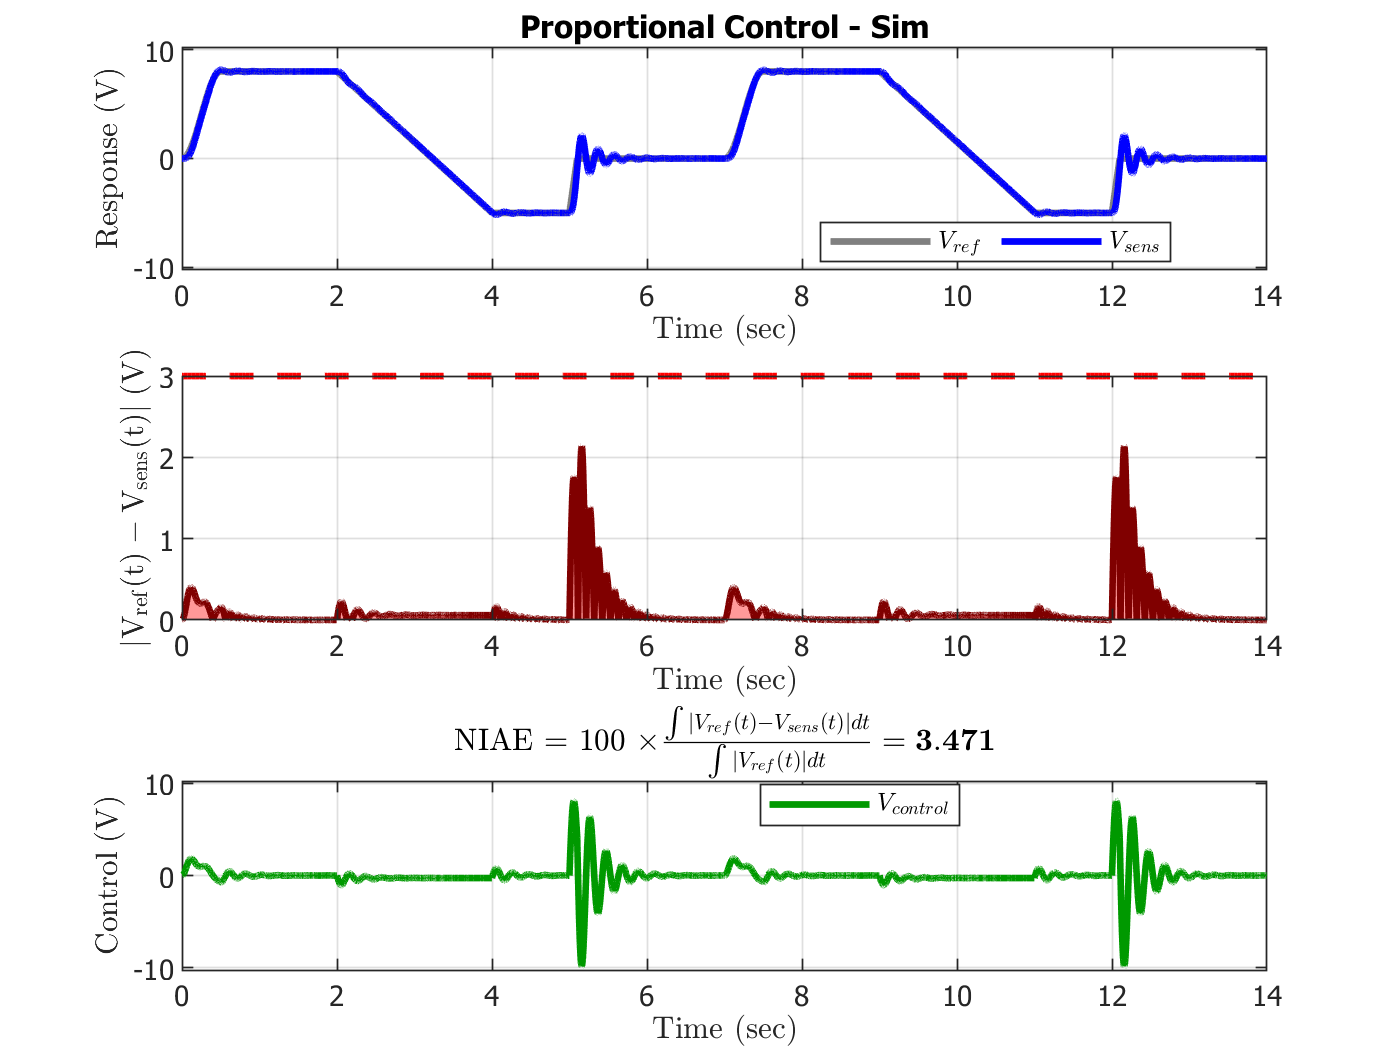

loop = motor * control;                                 % Declaration of OLTF L = C*P

closed_loop = minreal(loop / (1+loop));                 % Vsens closed-loop transfer function
closed_loop_vcontrol = minreal(control / (1+loop));     % Closed loop noise function

load reference
Vsens = lsim(closed_loop,Vref,t);                       % Simulate the response of Vsens

Vcontrol = lsim(closed_loop_vcontrol,Vref,t);           % Simulate response of Vcontrol noise 

niae_sim(1) = iae_analysis(t,Vref,Vsens,Vcontrol,'Proportional Control - Sim');

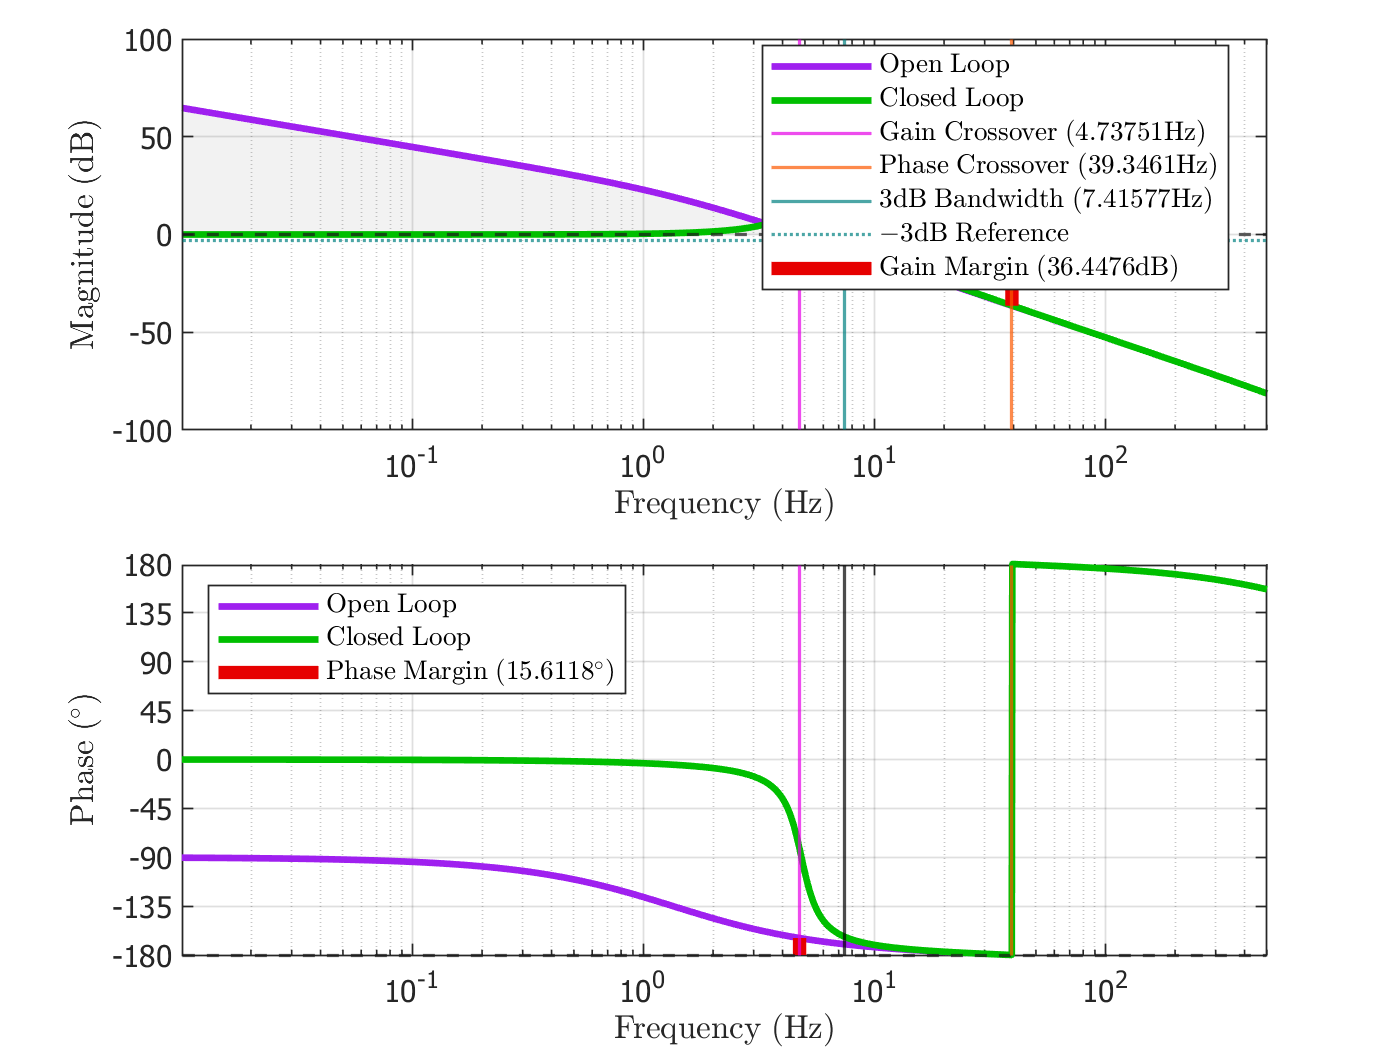

fdmetrics(1) = freq_domain_analysis(motor,control);

**[2 pts]**  Use the "Position Error Constant" and the "Velocity Error Constant" from the lecture notes (main course) to **compute and display** the theoretical steady-state error for a step input and a linear ramp input.  These results should match the simulated steady-state errors!

- From 0.5-2 seconds, the reference command Vref=8, so you should use this value as the amplitude for the steady-state error associated with a step input.

- From 2-4 seconds, the reference command is a linear ramp that goes from 8 to -5 volts.  These limits can be used to compute the slope which will then be the ramp amplitude for the steady-state error associated with a ramp input.

% -- Steady state error calculations
    % ZPK method using given MATLAB function

        % Position Error Constant 
            % Ess = a / Kp (From Zero-Pole Gain method)
        Kp = dcgain(loop);
        PECzpk = 8/Kp;
        
        % Velocity Error Constant
            % Ess = a / 1 + Kv (From Zero-Pole Gain/Type number analysis method)
        Kv = dcgain(loop * tf([1 0],[0 1]));
        a = (-5 - 8)/(4 - 2);       % a is ramp magnitude given above. R(s) = a/s^2 is laplace domain ramp input
        VECzpk = a /(1+Kv);

% -- Output steady state errors    
        fprintf('The Position Error Constant defined using type number analysis will yield %3.3f volts.\n',PECzpk)

The Position Error Constant defined using type number analysis will yield 0.000 volts.


        fprintf('The Velocity Error Constant defined using type number analysis will yield %3.3f volts.\n',VECzpk)

The Velocity Error Constant defined using type number analysis will yield -0.059 volts.


**[1 pts] ** Use the STEPINFO function in Matlab with the closed-loop LTI transfer function (Do NOT use STEPINFO with time-series data!!!) to compute the theoretical settling time and the percent overshoot for the **closed-loop system** due to a **unit** step.  All you need to do is call stepinfo and display the results in the LiveScript.

% -- Settling time and rise time for closed loop system
S = stepinfo(closed_loop)

S = struct with fields:
        RiseTime: 0.0383
    SettlingTime: 0.8656
     SettlingMin: 0.5818
     SettlingMax: 1.6470
       Overshoot: 64.6975
      Undershoot: 0
            Peak: 1.6470
        PeakTime: 0.1035

## Design 1:  Proportional Control - Experimental Validation  [4 pts total]

**[4 pts] ** Implement your proportional controller in the appropriate section of the lab5.m function, then evaluate this compensator design on the MSP432 emulator.  The closed-loop response data will automatically be saved to a mat-file called data1.mat.

NOTE:  The experiment is designed to capture data for 14 seconds; however, you will very likely see that the emulator takes much longer than 14 seconds to complete and save the data.  Do NOT attempt to run this section of code until after you have a working design from the previous section!  The simulation in the previous section runs much faster than the experiment!  You should also note that the experimental response includes noise added to the sensor output so you should expect to see variations caused by this noise.  It is acceptable to have a small number of times where signals clip, but it is not acceptable to have a large amount of clipping.

Load and plot the experimental data:

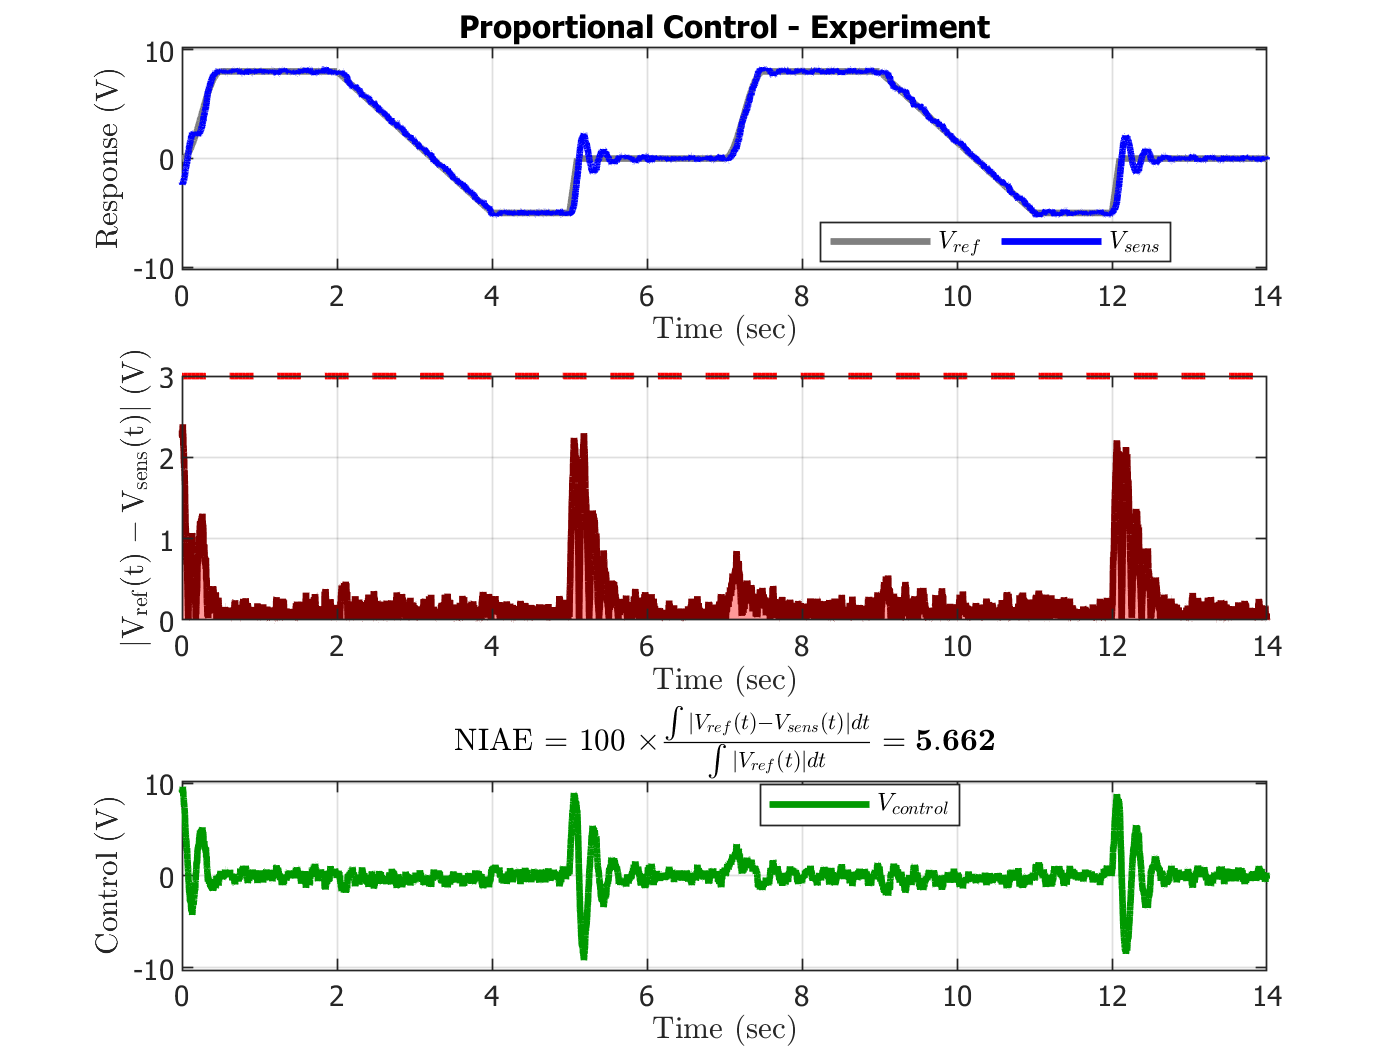

load data1
        
Vsens = data(:,1);     % feedback sensor (V)
Vcontrol = data(:,2);  % control signal (V)
Vref = data(:,3);      % reference command (V)

N = length(Vsens);
t = ts*[0:N-1];        % time (sec)

niae_exp(1) = iae_analysis(t,Vref,Vsens,Vcontrol,'Proportional Control - Experiment');

Recognizing that the noise in the experiment will cause these results to look different from the simulation, does the simulated time response generally match the experimental time response?  (select from the pulldown menu)

"Yes"

ans = "Yes"

## Design 2:  PI Control  - Simulation Analysis [10 pts total]

For this design, you will determine the parameters of a proportional + integral (PI) feedback compensator to meet all of the performance requirements.  Use a guess-and-check approach to determine the gains.

**[5 pts]**  Define and display your continuous-time controller design:

KP = 4.4;  % change this value

KI = 1.5;  % change this value

control = tf([KP KI],[1 0]);

**[2 pts] ** Evaluate this compensator design in Matlab using the motor model.  Analyze the time-domain and frequency domain results.

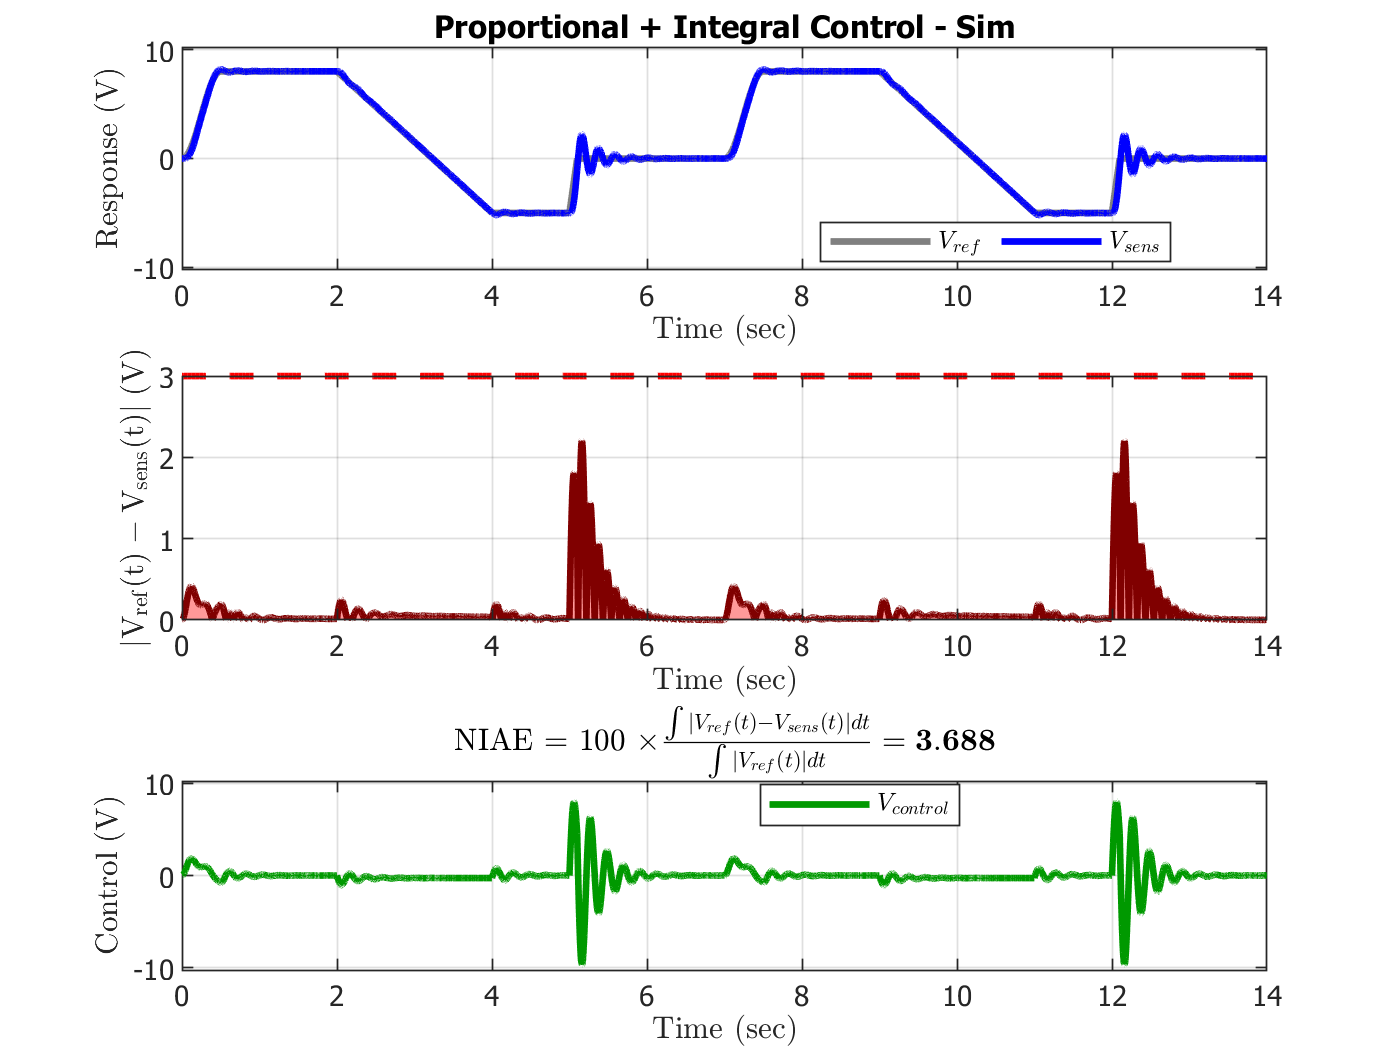

loop = motor * control;  % this line assumes that the motor LTI model is called motor

closed_loop = minreal(loop / (1+loop));      % closed-loop LTI object - Vsens output
closed_loop_vcontrol = minreal(control / (1+loop));  % closed-loop LTI object - Vcontrol output

load reference
Vsens = lsim(closed_loop,Vref,t);        % simulate the response of Vsens

Vcontrol = lsim(closed_loop_vcontrol,Vref,t);    % simulate the response of Vcontrol

niae_sim(2) = iae_analysis(t,Vref,Vsens,Vcontrol,'Proportional + Integral Control - Sim');

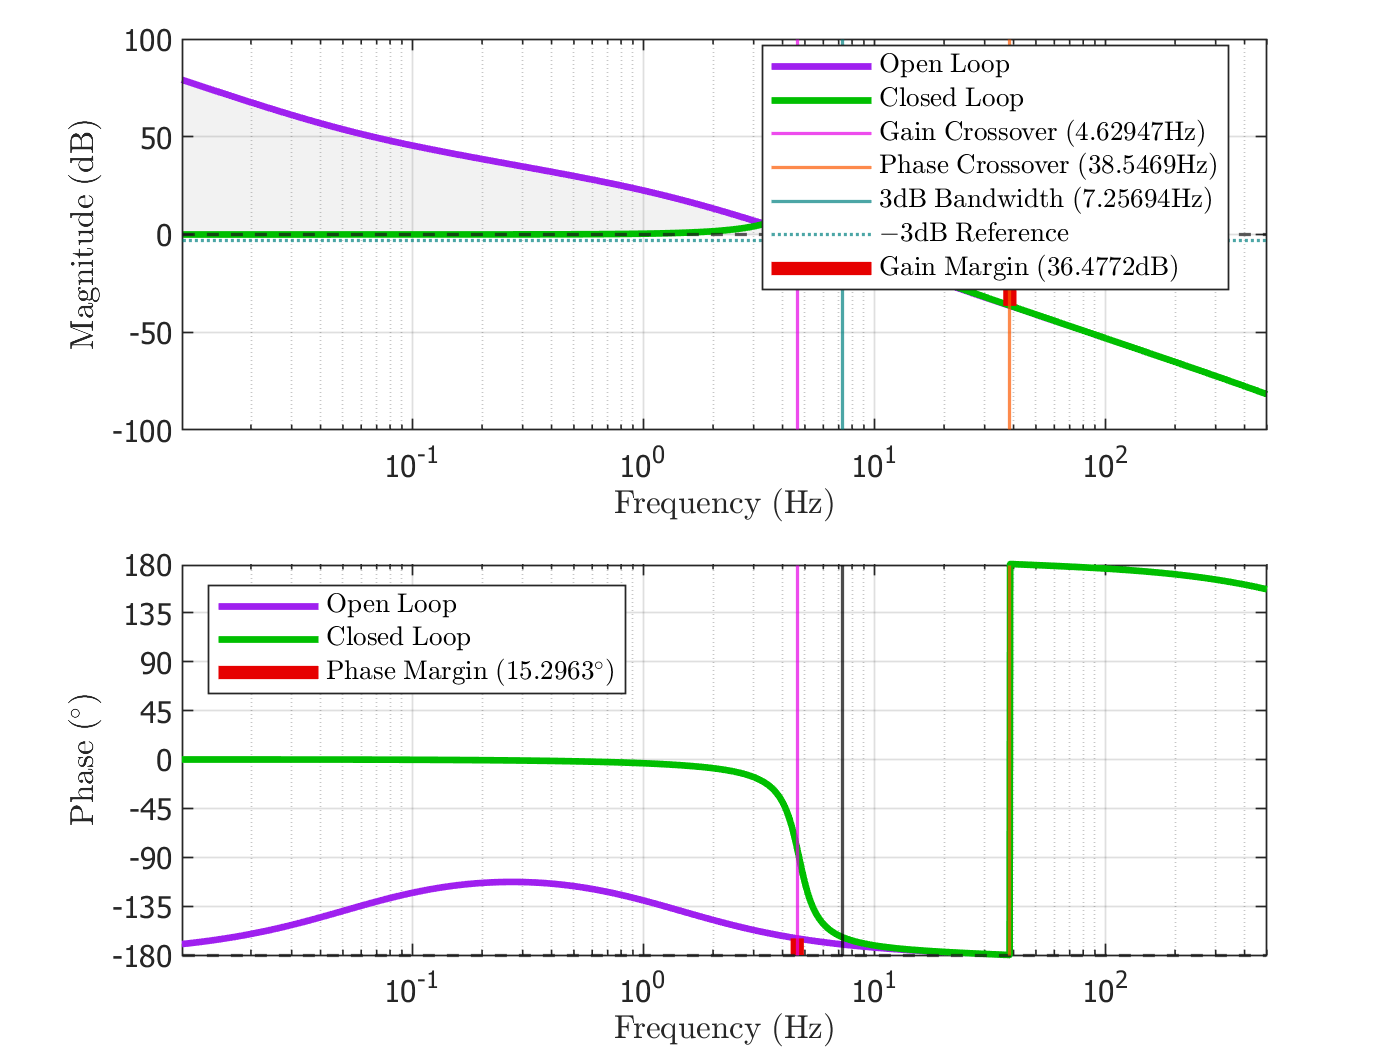

fdmetrics(2) = freq_domain_analysis(motor,control);

**[2 pts]**  Use the "Position Error Constant" and the "Velocity Error Constant" from the lecture notes (main course) to **compute and display** the theoretical steady-state error for a step input and a linear ramp input.

% -- Steady state error calculations
    % ZPK method using given MATLAB function

        % Position Error Constant 
            % Ess = a / Kp (From Zero-Pole Gain method)
        Kp = dcgain(loop);
        PECzpk = 8/Kp;
        
        % Velocity Error Constant
            % Ess = a / 1 + Kv (From Zero-Pole Gain/Type number analysis method)
        Kv = dcgain(loop * tf([1 0],[0 1]));
        a = (-5 - 8)/(4 - 2);       % a is ramp magnitude given above. R(s) = a/s^2 is laplace domain ramp input
        VECzpk = a /(1+Kv);

% -- Output steady state errors 
    % These will both have zero steady state errors because the system will be a type two system with the integral controller
    % so both will have zero steady state errors for step/ramp inputs
        fprintf('The Position Error Constant defined using type number analysis will yield %3.3f volts.\n',PECzpk)

The Position Error Constant defined using type number analysis will yield 0.000 volts.


        fprintf('The Velocity Error Constant defined using type number analysis will yield %3.3f volts.\n',VECzpk)

The Velocity Error Constant defined using type number analysis will yield -0.000 volts.


**[1 pts] ** Use the STEPINFO function in Matlab with the closed-loop LTI transfer function (Do NOT use STEPINFO with time-series data!!!) to compute the theoretical settling time and the percent overshoot for the **closed-loop system** due to a **unit** step.  All you need to do is call stepinfo and display the results in the LiveScript.

% -- Settling time and rise time for closed loop system
S = stepinfo(closed_loop)

S = struct with fields:
        RiseTime: 0.0391
    SettlingTime: 0.9833
     SettlingMin: 0.5769
     SettlingMax: 1.6571
       Overshoot: 65.7100
      Undershoot: 0
            Peak: 1.6571
        PeakTime: 0.1060

## Design 2:  PI Control - Experimental Validation  [4 pts total]

**[4 pts] ** Implement your proportional controller in the appropriate section of the lab5.m function, then evaluate this compensator design on the MSP432 emulator.  The closed-loop response data will automatically be saved to a mat-file called data2.mat.

NOTE:  The experiment is designed to capture data for 14 seconds; however, you will very likely see that the emulator takes much longer than 14 seconds to complete and save the data.  Do NOT attempt to run this section of code until after you have a working design from the previous section!  The simulation in the previous section runs much faster than the experiment!  You should also note that the experimental response includes noise added to the sensor output so you should expect to see variations caused by this noise.  It is acceptable to have a small number of times where signals clip, but it is not acceptable to have a large amount of clipping.

Load and plot the experimental data:

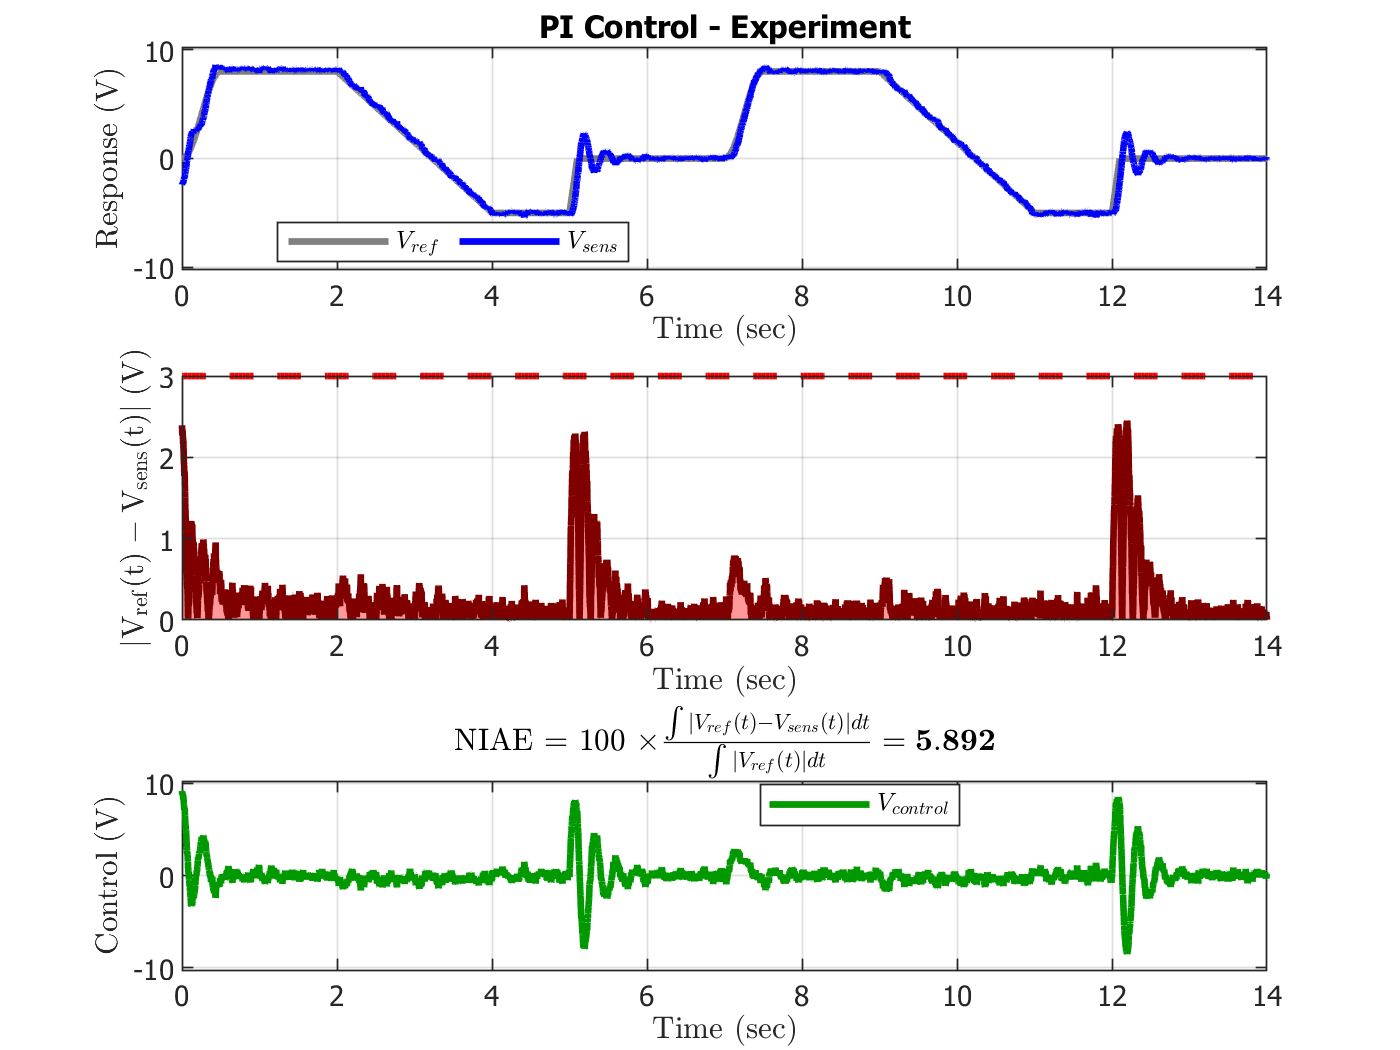

load data2
        
Vsens = data(:,1);     % feedback sensor (V)
Vcontrol = data(:,2);  % control signal (V)
Vref = data(:,3);      % reference command (V)

N = length(Vsens);
t = ts*[0:N-1];        % time (sec)

niae_exp(2) = iae_analysis(t,Vref,Vsens,Vcontrol,'PI Control - Experiment');

Recognizing that the noise in the experiment will cause these results to look different from the simulation, does the simulated time response generally match the experimental time response?  (select from the pulldown menu)

"Yes"

ans = "Yes"

## Design 3:  PID Control  - Simulation Analysis [10 pts total]

For this design, you will determine the parameters of a proportional + integral + derivative (PID) feedback compensator to meet all of the performance requirements.  You are welcome to try tuning the PID gains by trial and error; however, it is recommended that you use the PIDTUNE function in Matlab.  To use PIDTUNE, you will need to define the desired Phase Margin with the PIDTUNEOPTIONS function. Read the Matlab help for both functions before proceeding!

When you use PIDTUNE, you must select a controller "type".  There are **eighteen** different forms of controllers supported by PIDTUNE, ten of which are PID!  Note that even if you request one of the PID controller types, sometimes PIDTUNE will tell you that the best PID design is actually a PI design.  For this problem, your design MUST include a derivative term, so it is important to check the controller that Matlab gives you before using it!  If it does not include a derivative term, then you need to change to an alternative PID form.  A good option that usually performs well is the PIDF controller type.  You may want to adjust the overall gain of the PIDTUNE result by simply multiplying the output of PIDTUNE with your own overall gain.  You may also need to implement a strictly proper version of the PID controller (see the lab handouts).

**[5 pts]**  Define and display your continuous-time controller design:

% -- Declare PID options
    % Phase margin: 15 degrees      gain margin: 10dB       bandwidth: 5hz
options = pidtuneOptions('PhaseMargin',15);

% -- Design the PID controller
[control info] = pidtune(motor,'PIDF');     % Designs the PID compensator using given MATLAB function
control = tf(control);                      % Defines the transfer function of the controller
control = control * 4;                      % Multiplies controller by a static gain to achieve desired performance

**[2 pts] ** Evaluate this compensator design in Matlab using the motor model.  Analyze the time-domain and frequency domain results.

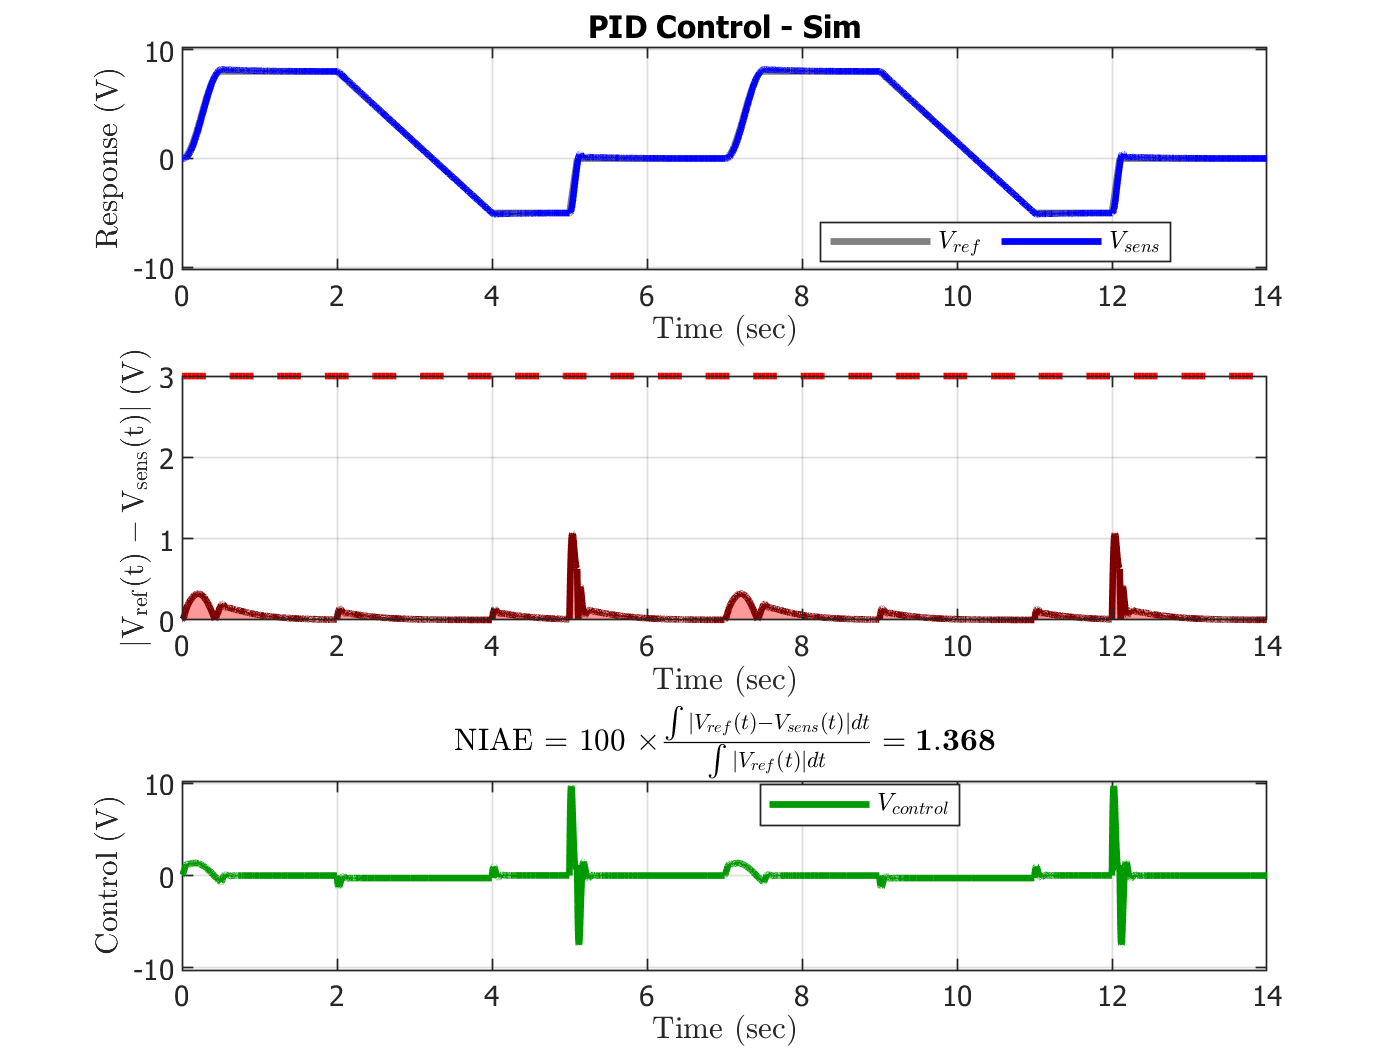

loop = motor * control;  % this line assumes that the motor LTI model is called motor

closed_loop = minreal(loop / (1+loop));      % closed-loop LTI object - Vsens output
closed_loop_vcontrol = minreal(control / (1+loop));  % closed-loop LTI object - Vcontrol output

load reference
Vsens = lsim(closed_loop,Vref,t);        % simulate the response of Vsens

Vcontrol = lsim(closed_loop_vcontrol,Vref,t);    % simulate the response of Vcontrol

niae_sim(3) = iae_analysis(t,Vref,Vsens,Vcontrol,'PID Control - Sim');

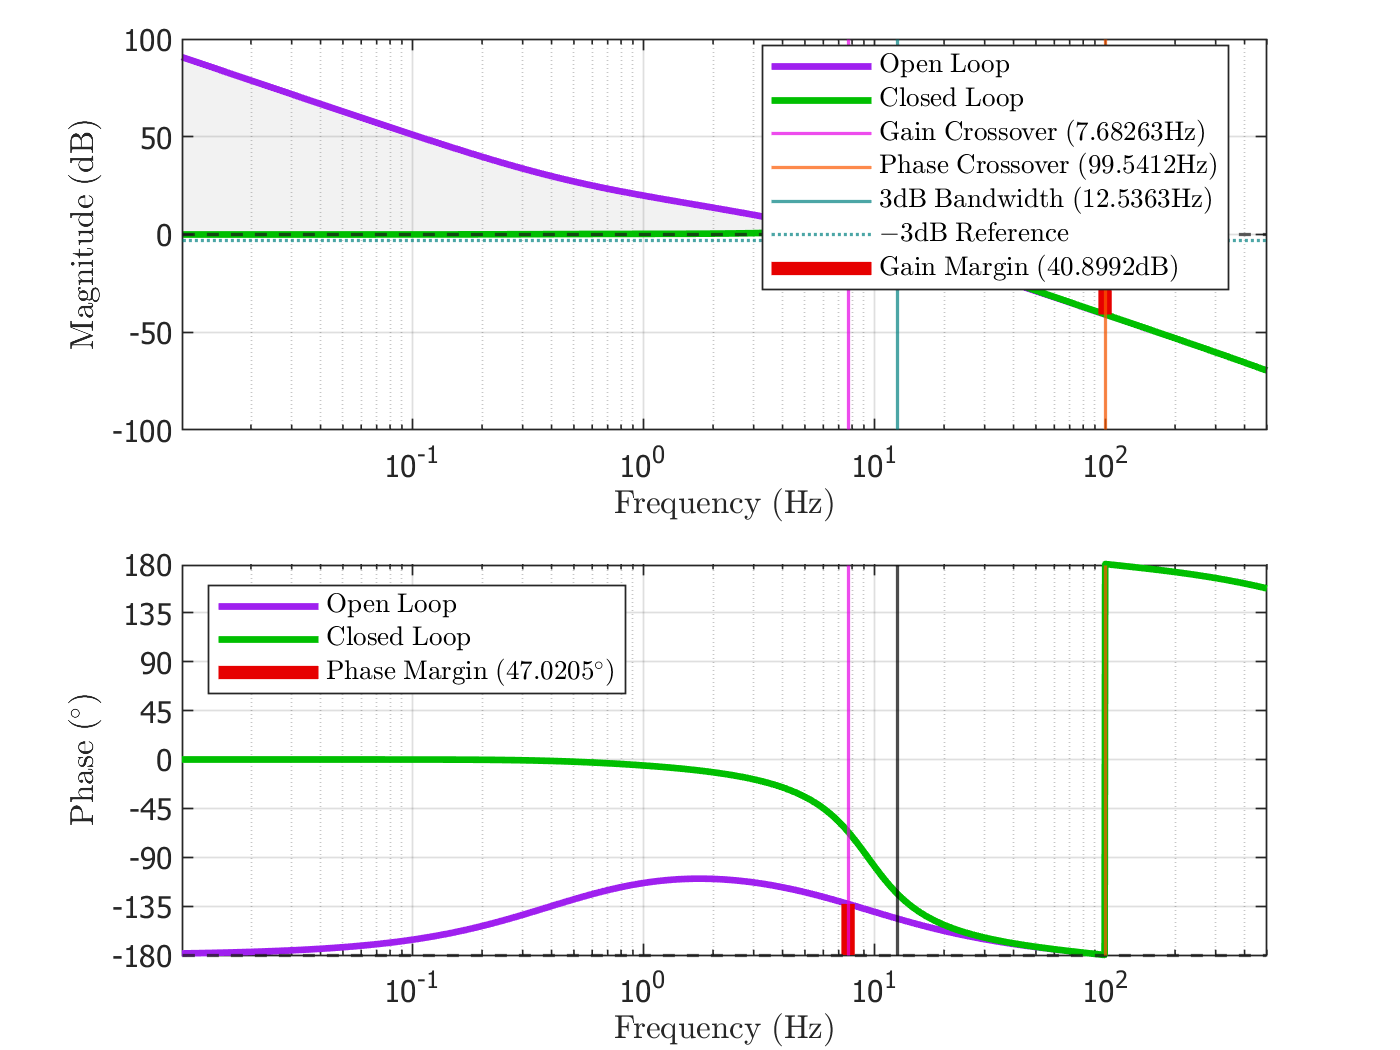

fdmetrics(3) = freq_domain_analysis(motor,control);

**[2 pts]**  Use the "Position Error Constant" and the "Velocity Error Constant" from the lecture notes (main course) to **compute and display** the theoretical steady-state error for a step input and a linear ramp input.

% -- Steady state error calculations
    % ZPK method using given MATLAB function

        % Position Error Constant 
            % Ess = a / Kp (From Zero-Pole Gain method)
        Kp = dcgain(loop);
        PECzpk = 8/Kp;
        
        % Velocity Error Constant
            % Ess = a / 1 + Kv (From Zero-Pole Gain/Type number analysis method)
        Kv = dcgain(loop * tf([1 0],[0 1]));
        a = (-5 - 8)/(4 - 2);       % a is ramp magnitude given above. R(s) = a/s^2 is laplace domain ramp input
        VECzpk = a /(1+Kv);

% -- Output steady state errors 
    % These will both have zero steady state errors because the system will be a type two system with the integral controller
    % so both will have zero steady state errors for step/ramp inputs
        fprintf('The Position Error Constant defined using type number analysis will yield %3.3f volts.\n',PECzpk)

The Position Error Constant defined using type number analysis will yield 0.000 volts.


        fprintf('The Velocity Error Constant defined using type number analysis will yield %3.3f volts.\n',VECzpk)

The Velocity Error Constant defined using type number analysis will yield -0.000 volts.


**[1 pts] ** Use the STEPINFO function in Matlab with the closed-loop LTI transfer function (Do NOT use STEPINFO with time-series data!!!) to compute the theoretical settling time and the percent overshoot for the **closed-loop system** due to a **unit** step.  All you need to do is call stepinfo and display the results in the LiveScript.

% -- Settling time and rise time for closed loop system
S = stepinfo(closed_loop)

S = struct with fields:
        RiseTime: 0.0257
    SettlingTime: 0.3262
     SettlingMin: 0.9095
     SettlingMax: 1.2281
       Overshoot: 22.8118
      Undershoot: 0
            Peak: 1.2281
        PeakTime: 0.0600

## Design 3:  PID Control - Experimental Validation  [4 pts total]

**[4 pts] ** Implement your proportional controller in the appropriate section of the lab5.m function, then evaluate this compensator design on the MSP432 emulator.  The closed-loop response data will automatically be saved to a mat-file called data3.mat.

NOTE:  The experiment is designed to capture data for 14 seconds; however, you will very likely see that the emulator takes much longer than 14 seconds to complete and save the data.  Do NOT attempt to run this section of code until after you have a working design from the previous section!  The simulation in the previous section runs much faster than the experiment!  You should also note that the experimental response includes noise added to the sensor output so you should expect to see variations caused by this noise.  It is acceptable to have a small number of times where signals clip, but it is not acceptable to have a large amount of clipping.

Load and plot the experimental data:

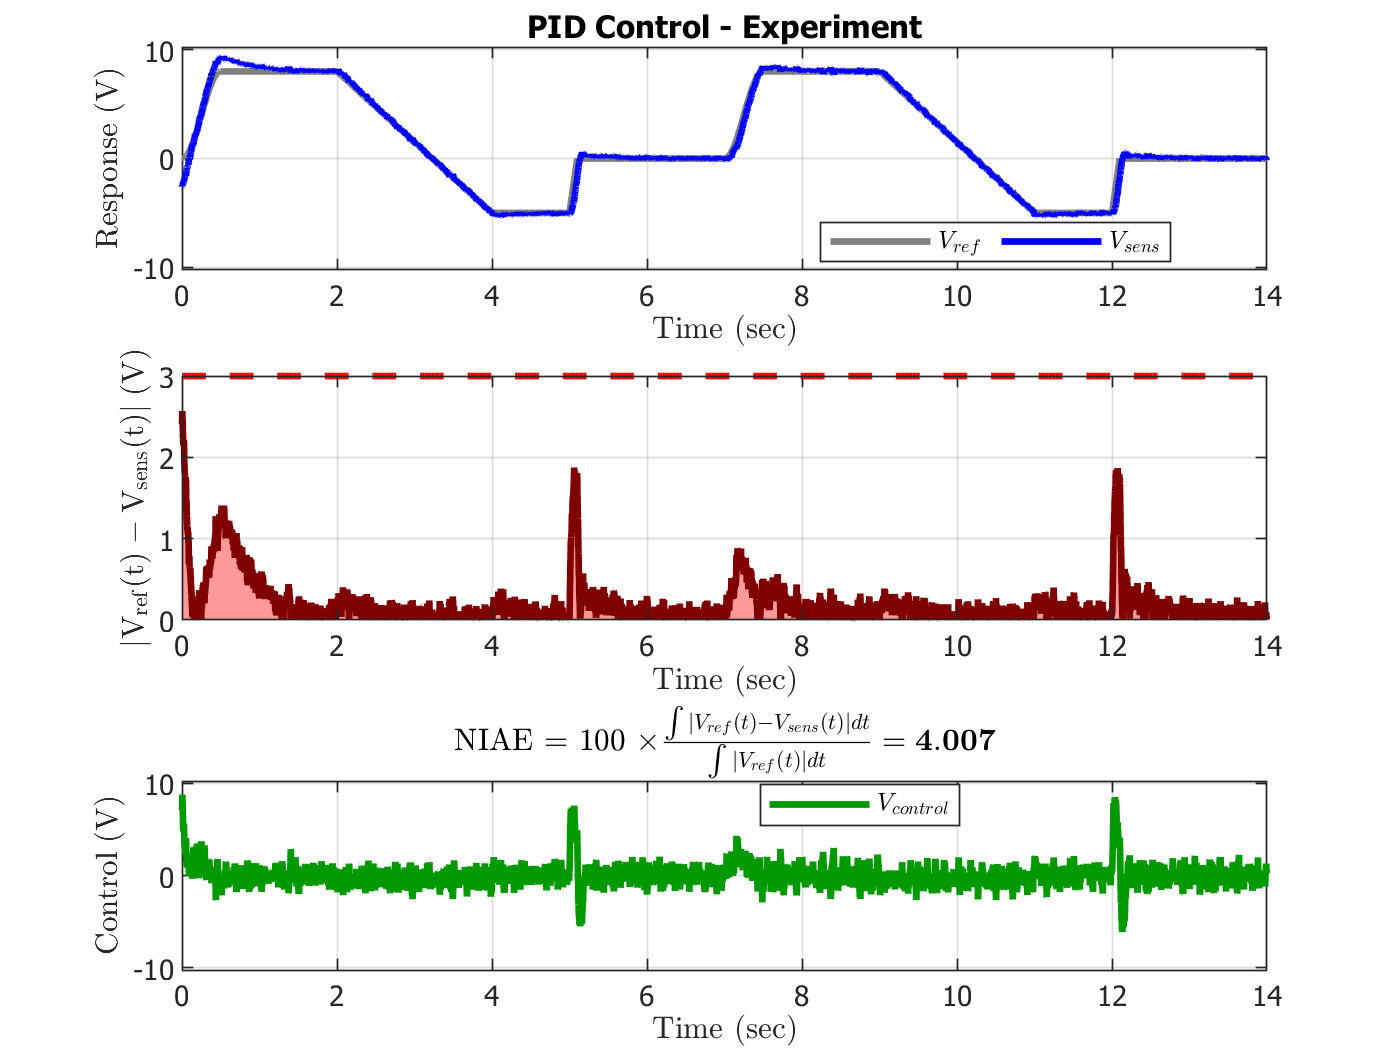

load data3
        
Vsens = data(:,1);     % feedback sensor (V)
Vcontrol = data(:,2);  % control signal (V)
Vref = data(:,3);      % reference command (V)

N = length(Vsens);
t = ts*[0:N-1];        % time (sec)

niae_exp(3) = iae_analysis(t,Vref,Vsens,Vcontrol,'PID Control - Experiment');

Recognizing that the noise in the experiment will cause these results to look different from the simulation, does the simulated time response generally match the experimental time response?  (select from the pulldown menu)

"Yes"

ans = "Yes"

## Design 4:  Lead Controller Design  [10 pts total]

For this design, you must determine the parameters of a lead compensator to meet all of the performance requirements. 

**[5 pts] ** Define and display your continuous-time controller design

% -- Definition of the lead-compensator 
    % Lead controller has a pole further away from the imaginary axis so
    % that it contributes a positive angle in time domain, maximum phase
    % that can be added is 90 degrees (P: S = -6)
leadnum = [1 1];                            % Lead Compensator Numerator
leaddenom = [1 5];                          % Lead compensator Denominator

leadControl = tf(leadnum,leaddenom);        % Transfer function of the lead controller

gain = 6;                                   % Multiply by a static gain k
leadControl = leadControl*gain              % Final definition of lead controller

leadControl =
 
  6 s + 6
  -------
   s + 5
 
Continuous-time transfer function.



**[2 pts] ** Evaluate this compensator design in Matlab using the motor model.  Analyze the time-domain and frequency domain results.

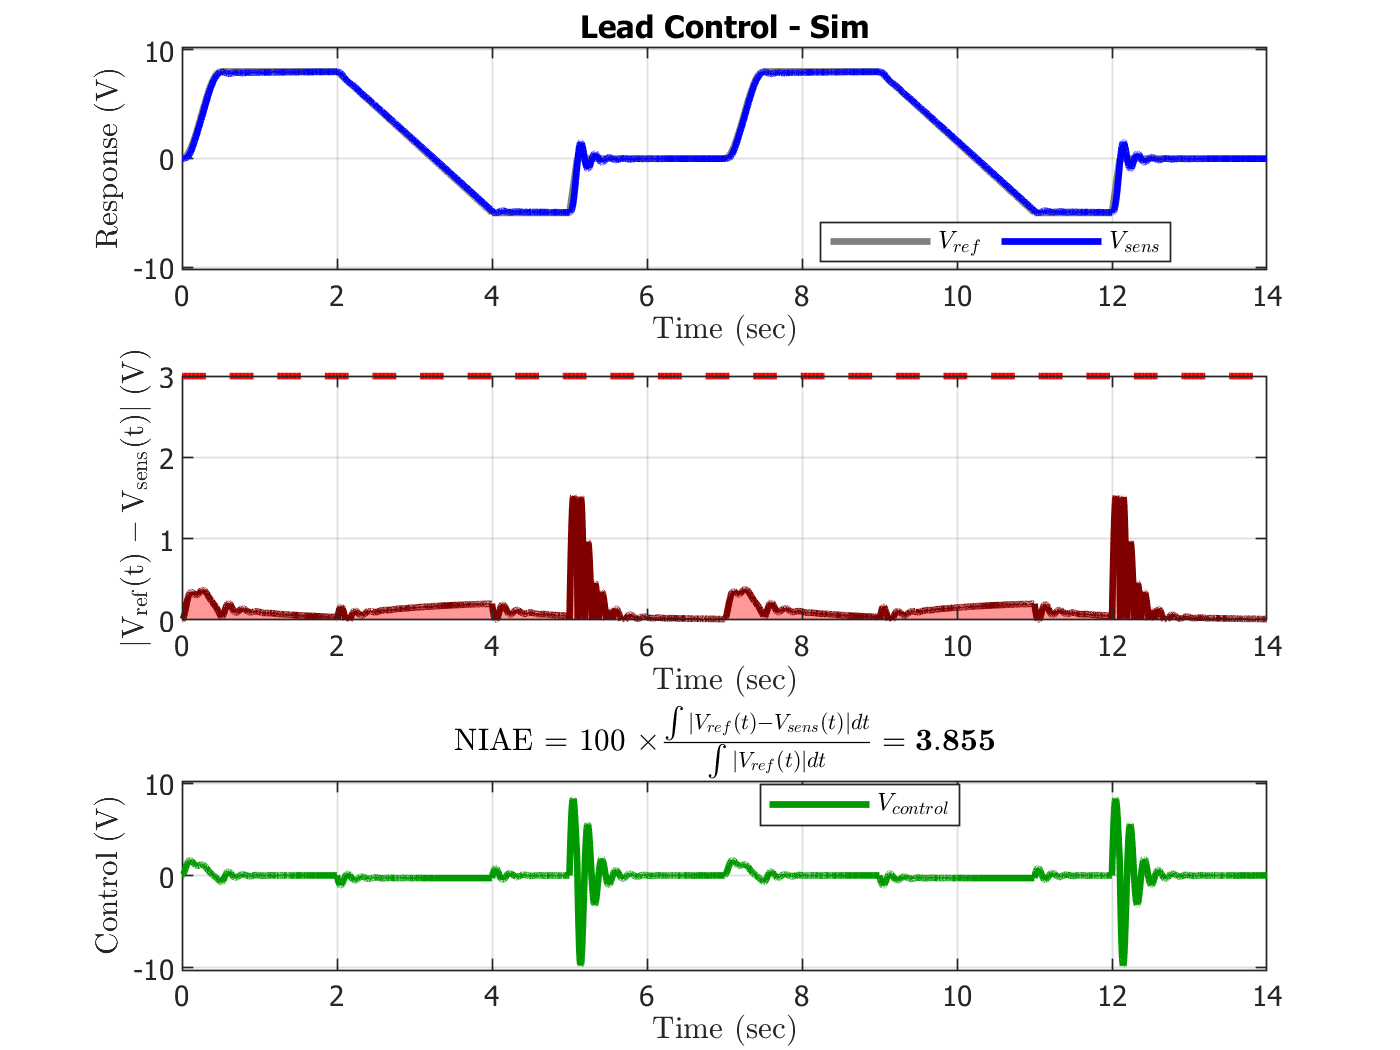

loop = motor * leadControl;  % this line assumes that the motor LTI model is called motor

closed_loop = minreal(loop / (1+loop));      % closed-loop LTI object - Vsens output
closed_loop_vcontrol = minreal(leadControl / (1+loop));  % closed-loop LTI object - Vcontrol output

load reference
Vsens = lsim(closed_loop,Vref,t);        % simulate the response of Vsens

Vcontrol = lsim(closed_loop_vcontrol,Vref,t);    % simulate the response of Vcontrol

niae_sim(4) = iae_analysis(t,Vref,Vsens,Vcontrol,'Lead Control - Sim');

fdmetrics(4) = freq_domain_analysis(motor,control);

**[2 pts]**  Use the "Position Error Constant" and the "Velocity Error Constant" from the lecture notes (main course) to **compute and display** the theoretical steady-state error for a step input and a linear ramp input.

% -- Steady state error calculations
    % ZPK method using given MATLAB function

        % Position Error Constant 
            % Ess = a / Kp (From Zero-Pole Gain method)
        Kp = dcgain(loop);
        PECzpk = 8/Kp;
        
        % Velocity Error Constant
            % Ess = a / 1 + Kv (From Zero-Pole Gain/Type number analysis method)
        Kv = dcgain(loop * tf([1 0],[0 1]));
        a = (-5 - 8)/(4 - 2);       % a is ramp magnitude given above. R(s) = a/s^2 is laplace domain ramp input
        VECzpk = a /(1+Kv);

% -- Output steady state errors 
    % Only the step input will be zero because it will only be a type 1
    % open loop system with the compensator not adding any free integrators
    % to the open loop transfer function
        fprintf('The Position Error Constant defined using type number analysis will yield %3.3f volts.\n',PECzpk)

The Position Error Constant defined using type number analysis will yield 0.000 volts.


        fprintf('The Velocity Error Constant defined using type number analysis will yield %3.3f volts.\n',VECzpk)

The Velocity Error Constant defined using type number analysis will yield -0.221 volts.


**[1 pts] ** Use the STEPINFO function in Matlab with the closed-loop LTI transfer function (Do NOT use STEPINFO with time-series data!!!) to compute the theoretical settling time and the percent overshoot for the **closed-loop system** due to a **unit** step.  All you need to do is call stepinfo and display the results in the LiveScript.

% -- Finding the performance metrics to a step function input
S = stepinfo(closed_loop)

S = struct with fields:
        RiseTime: 0.0346
    SettlingTime: 0.7498
     SettlingMin: 0.6620
     SettlingMax: 1.5342
       Overshoot: 53.4193
      Undershoot: 0
            Peak: 1.5342
        PeakTime: 0.0898

## Design 4:  Lead Controller Design - Experimental Validation  [4 pts total]

**[4 pts] ** Implement your proportional controller in the appropriate section of the lab5.m function, then evaluate this compensator design on the MSP432 emulator.  The closed-loop response data will automatically be saved to a mat-file called data4.mat.

NOTE:  The experiment is designed to capture data for 14 seconds; however, you will very likely see that the emulator takes much longer than 14 seconds to complete and save the data.  Do NOT attempt to run this section of code until after you have a working design from the previous section!  The simulation in the previous section runs much faster than the experiment!  You should also note that the experimental response includes noise added to the sensor output so you should expect to see variations caused by this noise.  It is acceptable to have a small number of times where signals clip, but it is not acceptable to have a large amount of clipping.

Load and plot the experimental data:

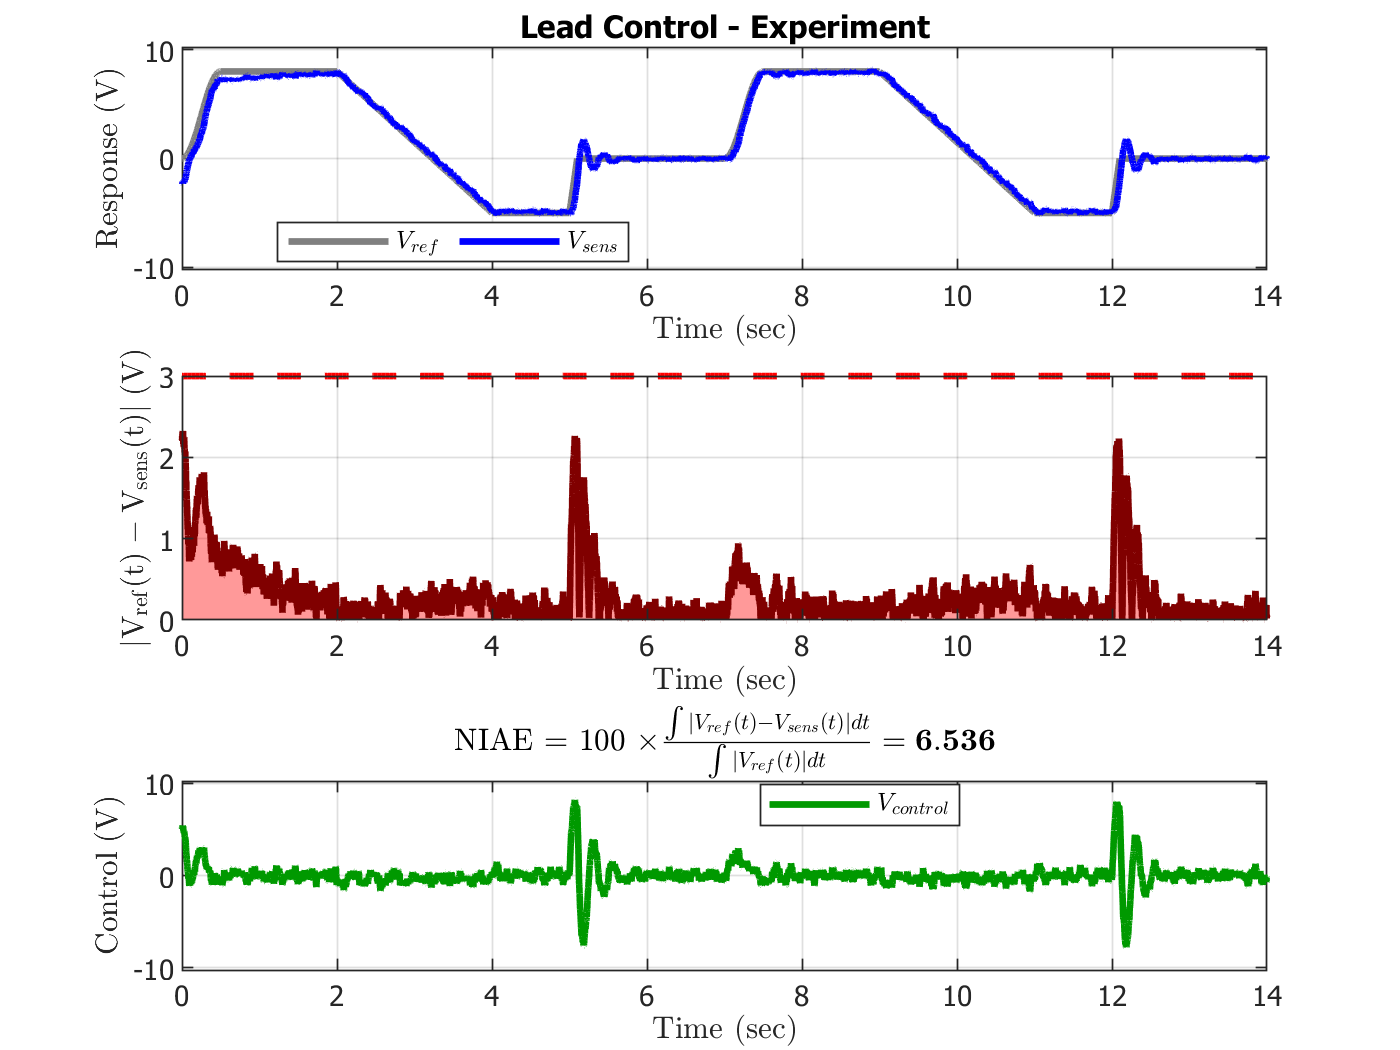

load data4
        
Vsens = data(:,1);     % feedback sensor (V)
Vcontrol = data(:,2);  % control signal (V)
Vref = data(:,3);      % reference command (V)

N = length(Vsens);
t = ts*[0:N-1];        % time (sec)

niae_exp(4) = iae_analysis(t,Vref,Vsens,Vcontrol,'Lead Control - Experiment');

Recognizing that the noise in the experiment will cause these results to look different from the simulation, does the simulated time response generally match the experimental time response?  (select from the pulldown menu)

"Yes"

ans = "Yes"

## Summary of Performance Results [4 pts total]

**[2 pt]**  The following table summarizes the performance results of each of your designs using the Matlab TABLE function.  This table includes the NIAE (simulation and experiment), Bandwidth, Gain Margin, and Phase Margin metrics.  There is nothing for you to change here unless your code above does not provide the correct data for this section to run properly.

BW = [fdmetrics(:).BW_Hz];
GM = [fdmetrics(:).GM_dB];
PM = [fdmetrics(:).PM_deg];

T = table(niae_sim',niae_exp',BW',GM',PM');
T.Properties.RowNames = {'Design 1:  P','Design 2:  PI', ...
    'Design 3:  PIDF','Design 4:  Lead'};
T.Properties.VariableNames = {'NIAE Sim [%]','NIAE Experiment [%]', ...
    'BW [Hz]','GM [dB]','PM [deg]'};
disp(T);

                       NIAE Sim [%]    NIAE Experiment [%]    BW [Hz]    GM [dB]    PM [deg]
                       ____________    ___________________    _______    _______    ________
    Design 1:  P          3.4713             5.6616           7.4158     36.448      15.612 
    Design 2:  PI         3.6881             5.8922           7.2569     36.477      15.296 
    Design 3:  PIDF       1.3676             4.0066           12.536     40.899       47.02 
    Design 4:  Lead       3.8552             6.5361           12.536     40.899       47.02 


**[2 pts]  **Which of your four designs has the best overall performance?  Justify your answer using the information in this table.

The best overall performance was the PIDF controller. This was the best controller because of the NIAE was so much lower than the other controllers in both the simulation and the actual emulator experiment. The Simulation NIAE was within 2%, where the NIAE experiment was within 5%. This also had the highest stability because it shared the largest phase margin of 47 degrees.

 The worst design was the Lead Compensator in terms of error elimination. The lead compensator was the lowest beacuse it had the highest NIAE of all the compensators. However, Lead Compensators are not meant to decrease error but to increase stability and response time, which can be seen in the high phase margin which indicates high stability of the system. 